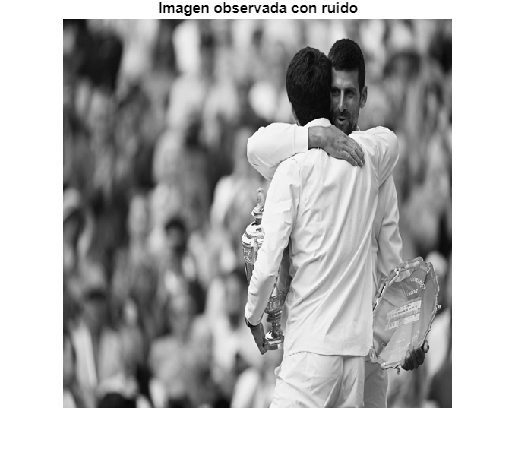

load('im_3_level_1.mat')
figure;
imshow(im, []);
title('Imagen observada con ruido');

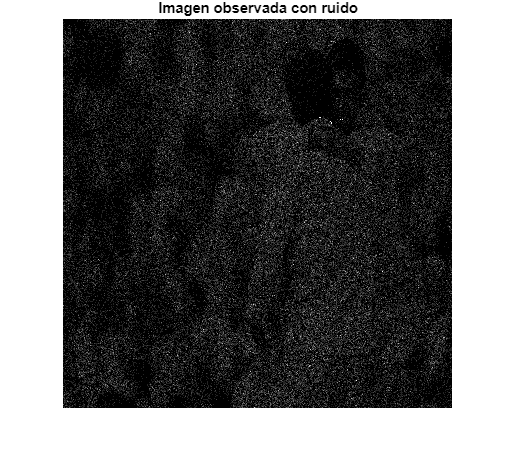

imbl= imread('im_3_level_1.png'); % Cambia 'imagen_baja_luz.png' por el nombre de tu imagen
imbl = double(imbl);
figure;
imshow(imbl, []);
title('Imagen observada con ruido');

% Tamaño de la imagen
[alto, ancho] = size(im);

% Parámetros ADMM
max_iter = 2;  % Número máximo de iteraciones
rho = 0.9;         % Parámetro de ajuste para actualización de multiplicadores de Lagrange
lambda = 0.1;    % Parámetro de regularización (ajustar según la cantidad de suavizado deseada)

% Inicialización
x = ones(alto, ancho); % Suponemos una imagen inicial constante
z = x; % Variables auxiliares
u = zeros(alto, ancho); % Multiplicadores de Lagrange inicializados en cero

% Implementación del algoritmo ADMM
for iter = 1:max_iter
    % Actualización de "x" (minimizar la función de verosimilitud y términos de Lagrange)
    x = (sum(sum(x - imbl .* log(x) + x + gammaln(imbl + 1))))

    
    % Actualización de "z" (minimizar la función de penalización y términos de Lagrange)
    z = max(x + u, 0)
    
    % Actualización de los multiplicadores de Lagrange "u"
    u = u + x - z
    
    % Comprobar convergencia
end

x = 1.6712e+07

z = 1.0e+07 *

    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712
    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    1.6712    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 8.7617e+12

z = 1.0e+12 *

    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617
    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    8.7617    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 4.5936e+18

z = 1.0e+18 *

    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936
    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    4.5936    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 2.4084e+24

z = 1.0e+24 *

    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084
    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    2.4084    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 1.2627e+30

z = 1.0e+30 *

    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627
    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    1.2627    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 6.6201e+35

z = 1.0e+35 *

    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201
    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    6.6201    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 3.4709e+41

z = 1.0e+41 *

    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709
    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    3.4709    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 1.8197e+47

z = 1.0e+47 *

    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197
    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    1.8197    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 9.5406e+52

z = 1.0e+52 *

    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406
    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    9.5406    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

x = 5.0020e+58

z = 1.0e+58 *

    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020
    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    5.0020    

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

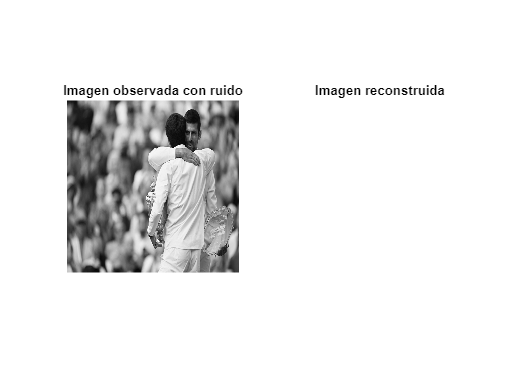


% Mostrar resultados
figure;
subplot(1, 2, 1);
imshow(im, []);
title('Imagen observada con ruido');

subplot(1, 2, 2);
imshow(x, []);
title('Imagen reconstruida');